clc; clear variables;

# 2 Zeit diskrete Signale

## 2.2 Faltung

x = [5 4 3 2 1];
u = [1 1 1];

y = faltung(x,u);

%Probe
%falt = conv(x,u)

## 2.3 Formatierung von Graphen

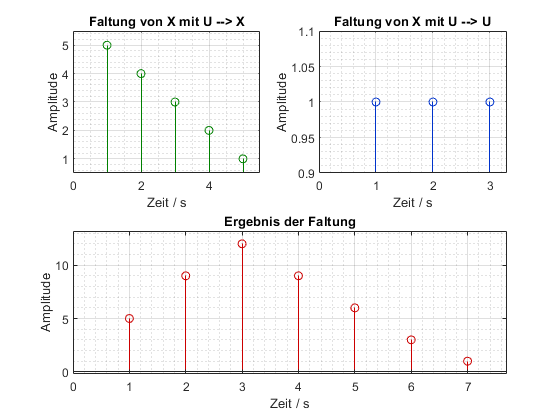

figure (1); 
subplot(2,2,1)
stem(x,'Color',[0 0.5 0])
stem_properties('Faltung von X mit U --> X','Zeit / s','Amplitude',x);

subplot(2,2,2)
stem(u,'Color',[0 0.2 0.8])
stem_properties('Faltung von X mit U --> U','Zeit / s','Amplitude',u);

subplot(2,2,[3,4])
stem(y,'Color',[0.8 0 0])
stem_properties('Ergebnis der Faltung','Zeit / s','Amplitude',y);

## 2.4 Systemeigenschaften

nSymbols = 2^3;
%Erzeugung von 2 zufälligen Signalen

rng(1)
data1 = randn(1, nSymbols);                 
rng(13)                         % gleicher Seed bedeutet gleiche Zufallszahlenfolge
data2 = randn(1, nSymbols);

%Dirac zur späteren Kausalitätsprüfung
dirac_1_pos = floor(length(data1)/2);
dirac = zeros(1, length(data1));
dirac(dirac_1_pos) = 1;

#### Skalierer          y[k] = 2*x[k]

a = 2;
scaled_y1 = scaler(data1, a);
scaled_y2 = scaler(data2, a);

% Linearitätsprüfung (linear = 1)
isequal(scaled_y1 + scaled_y2 , scaler((data1+data2), a))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(scaled_y1, -t0);
eingang = scaler(circshift(data1, -t0), a);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_sca = scaler(dirac, a);

kausalitaet(dir_sca);

kausal = 1

#### Offset (Gleichanteil)            y[k] = x[k] + 1

o = 3;
offset_y1 = offset(data1, o);
offset_y2 = offset(data2, o);

% Linearitätsprüfung (linear = 1)
isequal(offset_y1 + offset_y2 , offset((data1+data2), o))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(offset_y1, -t0);
eingang = offset(circshift(data1, -t0), o);

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_off = offset(dirac, o);

kausalitaet(dir_off);

kausal = 0

#### Zeitspiegelung    y[k] = x[-k]

mirror_y1 = flip(data1);
mirror_y2 = flip(data2);

% Linearitätsprüfung (linear = 1)
isequal(mirror_y1 + mirror_y2 , flip(data1+data2))

ans = logical
   1



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mirror_y1, -t0);
eingang = flip(circshift(data1, -(-t0)));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_mir = flip(dirac);

kausalitaet(dir_mir);

kausal = 1

#### Differenzenbildung (Element wird vom Nachfolgenden subtrahiert) y[k] = x[k]-x[k-1]

diff_y1 = difference(data1);
diff_y2 = difference(data2);

% Linearitätsprüfung (linear = 1)
a1 = diff_y1 + diff_y2;
a2 = difference(data1+data2);
isequal(round(a1,4) , round(a2,4))  % round wird wegen rundungsfehlern benutzt

ans = logical
   1


%isequal(diff_y1 + diff_y2 , difference(data1+data2))

% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(diff_y1, -t0);
eingang = difference(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_diff = difference(dirac);

kausalitaet(dir_diff);

kausal = 1

#### Modulation (Multiplikation mit Trägerschwingung)        y[k] = x[k]*cos((pi/4)*k)

mod_y1 = simple_mod(data1);
mod_y2 = simple_mod(data2);

% Linearitätsprüfung (linear = 1)
isequal(mod_y1 + mod_y2 , simple_mod(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(mod_y1, -t0);
eingang = simple_mod(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   0



% Kausalitätsprüfung (kausal = 1)
dir_mod = simple_mod(dirac);

kausalitaet(dir_mod);

kausal = 1

#### Quantisierer       y[k] = gerundet(x[k])

quant_y1 = round(data1);
quant_y2 = round(data2);

% Linearitätsprüfung (linear = 1)
isequal(quant_y1 + quant_y2 , round(data1+data2))

ans = logical
   0



% Zeitinvarianzprüfung (zeitinvariant = 1)
t0 = 5;
ausgang = circshift(quant_y1, -t0);
eingang = round(circshift(data1, -t0));

isequal(ausgang, eingang)

ans = logical
   1



% Kausalitätsprüfung (kausal = 1)
dir_quan = round(dirac);

kausalitaet(dir_quan);

kausal = 1

## 2.5 FIR (Finite Impulse Response) Systeme

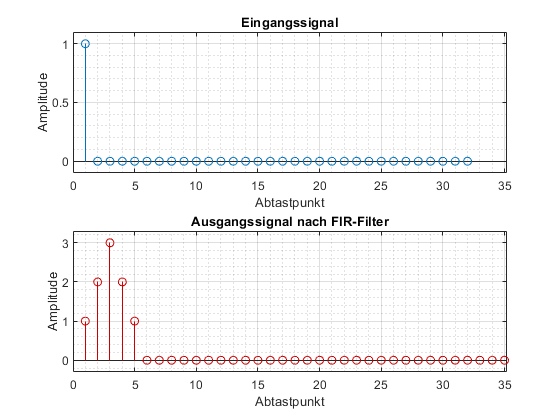

n_Symbols = 2^5;

%Dirac-Impuls
dirac_puls = zeros(1, n_Symbols);
dirac_puls(1) = 1;

coef = [1 2 3 2 1];                           %Vorwärstzweig
fir_system = FIR(dirac_puls, 4, coef);
%zum Probe ([1 0 0 0 0] = Rückwärtszweig)
%fir_system = filter(coef, [1 0 0 0 0], dirac_puls);        


figure (2)
subplot(2,1,1)
stem(dirac_puls)
stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
subplot(2,1,2)
stem(fir_system, 'Color',[0.8 0 0])
stem_properties('Ausgangssignal nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
xlim([0 length(dirac_puls)+length(dirac_puls)/10]); %zur Zentrierung mit Eingangssignal

#### **Testen für beliebige Eingangssignale mit Probe durch Faltung der Impulsantwort**

#### *1. Zufallstestsignal*

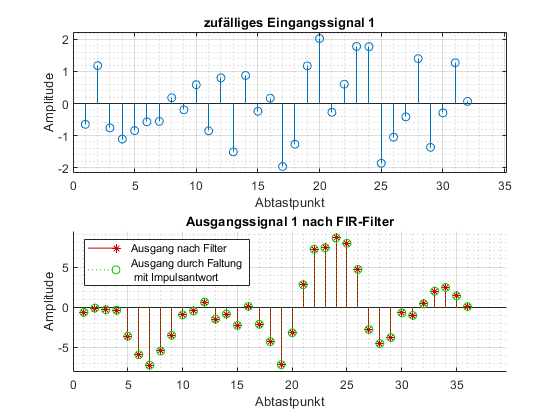

rng(1)
data3 = randn(1, n_Symbols);                %generieren des Zufallssignals

fir_system3 = FIR(data3, 4, coef);          %Ausgangssignalbestimmung durch Filterfunktion
fir_faltung3 = faltung(data3, coef);        %Ausgangssignalbestimmung durch Faltung mit Impulsantwort

figure (3)
subplot(2,1,1)
stem(data3)
stem_properties('zufälliges Eingangssignal 1', 'Abtastpunkt', 'Amplitude', data3)

subplot(2,1,2)
hold on
stem(fir_system3, 'Color',[0.8 0 0],'Marker',"*")
stem(fir_faltung3, 'Color',[0 0.8 0],'LineStyle',":")
stem_properties('Ausgangssignal 1 nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_faltung3) 
hold off
legend('Ausgang nach Filter','Ausgang durch Faltung \newline mit Impulsantwort','Location','northwest')

#### *2. Zufallstestsignal*

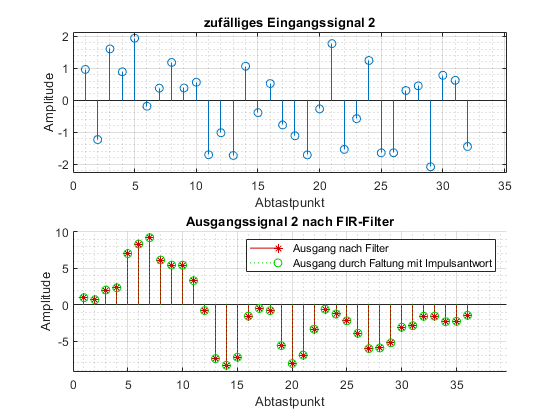

rng(13)                         
data4 = randn(1, n_Symbols);              

fir_system4 = FIR(data4, 4, coef);
fir_faltung4 = faltung(data4, coef);

figure (4)
subplot(2,1,1)
stem(data4)
stem_properties('zufälliges Eingangssignal 2', 'Abtastpunkt', 'Amplitude', data4)

subplot(2,1,2)
hold on
stem(fir_system4, 'Color',[0.8 0 0],'Marker',"*")
stem(fir_faltung4, 'Color',[0 0.8 0],'LineStyle',":")
stem_properties('Ausgangssignal 2 nach FIR-Filter', 'Abtastpunkt', 'Amplitude', fir_faltung4)
hold off
legend('Ausgang nach Filter','Ausgang durch Faltung mit Impulsantwort')

## IIR - Infinite Impulse Response

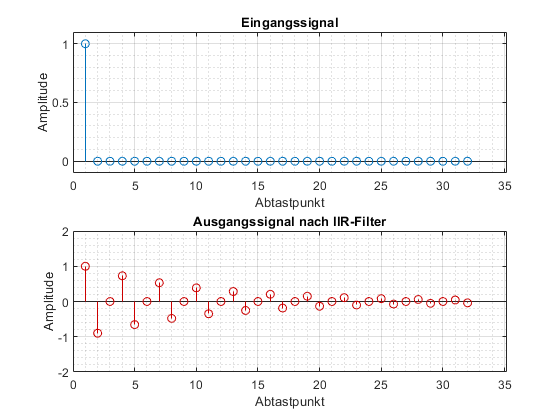

coef1 = [1 0 0];                        %Vorwärtszweig
coef2 = [1 0.9 0.81];                   %Rückkoppelzweig
iir_system = IIR(dirac_puls, 2, coef1, coef2);

figure (5)
subplot(2,1,1)
stem(dirac_puls)
stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
subplot(2,1,2)
stem(iir_system, 'Color',[0.8 0 0])
stem_properties('Ausgangssignal nach IIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
xlim([0 length(dirac_puls)+(length(dirac_puls)/10)]); %zur Zentrierung mit Eingangssignal
ylim([-2 2])


% %Zur Probe:
% iir_system2 = filter(coef1, [1 0.9 0.81], dirac_puls);
% figure (6)
% subplot(2,1,1)
% stem(dirac_puls)
% stem_properties('Eingangssignal', 'Abtastpunkt', 'Amplitude', dirac_puls)
% subplot(2,1,2)
% stem(iir_system2, 'Color',[0.8 0 0])
% stem_properties('Ausgangssignal nach IIR-Filter', 'Abtastpunkt', 'Amplitude', fir_system)
% ylim([-2 2])


## Stabilitäts Probe der Übertragungsfunktion

coef3 = [1 0.9 0.81];                       %gegebene Koeffizienten

Pol = roots(coef3);                         %bestimmen der Nullstellen des Nennerpolynoms der Übertragungsfunktion --> Polstellen
abs(Pol)                                    %Betrag der Polstelle in der komplexen Ebene

ans =     0.9000
    0.9000


Kreisumfang = linspace (0, 2*pi);           %Erstellung des Einheitskreises      
x = cos(Kreisumfang);
y = sin(Kreisumfang);

#### 1. Methode: Einheitskreis

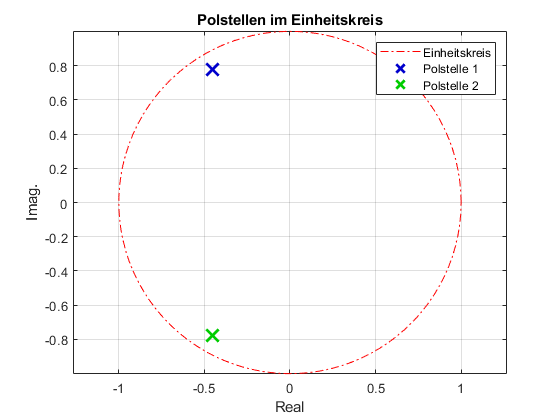

figure (6)
plot(x,y,'Color','r', "LineStyle",'-.');    %Einheitskreis
axis equal;                                 %mit symmetrischen Achsen
hold on
 % Sobald die Beträge < 1 und damit im Einheitkreis sind  --> System ist stabil
plot(real(Pol(1)),imag(Pol(1)),'Marker','x','Color',[0 0 0.8],"MarkerSize",13,'LineStyle','none','linewidth',2)        
plot(real(Pol(2)),imag(Pol(2)),'Marker','x','Color',[0 0.8 0],"MarkerSize",13,'LineStyle','none','linewidth',2)    
xlabel('Real')
ylabel('Imag.')
grid on;
hold off;
title ('Polstellen im Einheitskreis')
legend ('Einheitskreis','Polstelle 1','Polstelle 2')        

#### 2.Methode: Darstellung im 3D-Plot (meshgrid)

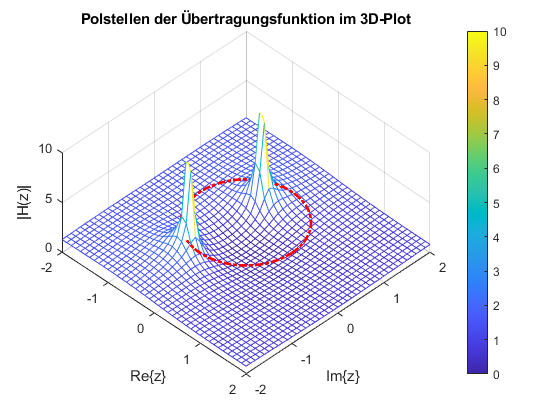

[x_Real,y_Imag] = meshgrid (-2:0.1:2);   %quadratisches "Meshgrid" (Grenzen von -2 bis 2 in 0,1 Schritten) --> spannt die komplexe Ebene auf
z = x_Real + 1j * y_Imag;                %z soll auf der komplexen Ebene dargestellt werden
x2 = z.^2 ./ (z.^2 + 0.9*z + 0.81);      %Übertragungsfunktion (Herleitung im Protokoll)

figure (7);
mesh (x_Real, y_Imag, abs(x2))                          %Plotten vom 3D-Raum
line(x, y , 3*ones(size(Kreisumfang)),'linewidth',2,'Color','red','LineStyle','-.')    %Einheitskreis (z-Koordinate besteht nur aus Einsen, die durch den Vorfaktor auf 3 (zur besseren Ansicht) hochgeschoben sind)
view([45 60])                                           %schräge Ansicht
xlim ([-2 2])
ylim ([-2 2])
zlim ([0 10]); 
caxis ([0,10]);                          %caxis = Limit für die Colormap
xlabel ('Re\{z\}')                       %(Achsenbeschriftung wie in Vorlesung)
ylabel ('Im\{z\}')
zlabel ('|H(z)|')
title  ('Polstellen der Übertragungsfunktion im 3D-Plot')
colorbar

#### FIR-System aus einem IIR-System

coef4 = [1 2 3 2 1];                   %Vorwärtszweig
coef5 = [1 0 0 0 0];                   %Rückkoppelzweig

fir_aus_iir = IIR(dirac_puls, 4, coef4, coef5);

## Erregung mit nichtkausaler komplexer Exponentialfolge

#### z_inf = 1.1

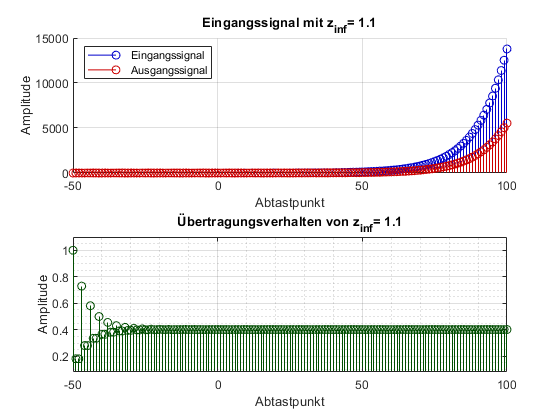

k = -50:1:100;                  %gegeben
z = 1.1;                        %gegeben

x= z.^k;                        %komplexe Exponentialfolge

y = IIR(x,2,coef1,coef2);       %Filterung der Folge mit bekanntem IIR-Filter

figure(8)
subplot (2,1,1)
hold on
stem (k,x, 'Color',[0 0 0.8])
stem (k,y, 'Color',[0.8 0 0])
hold off
legend ('Eingangssignal', 'Ausgangssignal','Location','northwest')
xlabel ('Abtastpunkt')
ylabel ('Amplitude')
title ('Eingangssignal mit z_{inf}= 1.1')
grid on

q = y ./ x;                   %Quotient aus Ausgangssignal zu Eingangssignal
subplot (2,1,2)
stem (k,q,'Color',[0 0.3 0])
stem_properties('Übertragungsverhalten von z_{inf}= 1.1', 'Abtastpunkt', 'Amplitude', q)
xlim([-50 100])


Y=polyval(coef1,z);         %Auswertung des Zählerpolynoms
X=polyval(coef2,z);         %Auswertung des Nennerpolynoms

H_z = Y/X

H_z = 0.4020

#### z_inf = 1.1*e^(j*(pi/7)

z1= 1.1 * exp(1j*pi/7);

losung0 = ((1.1 * exp(1j*pi/7))^2)/(((1.1 * exp(1j*pi/7))^2)+(0.9*(1.1 * exp(1j*pi/7)))+0.81);
losung1 = ((z1)^2)/(((z1)^2)+(0.9*(z1))+0.81);

Y1=polyval(coef1,z1);       %Auswertung des Zählerpolynoms
X1=polyval(coef2,z1);       %Auswertung des Nennerpolynoms

H_z1 = Y1/X1

H_z1 = 0.3980 + 0.1623i

abs(H_z1)

ans = 0.4298

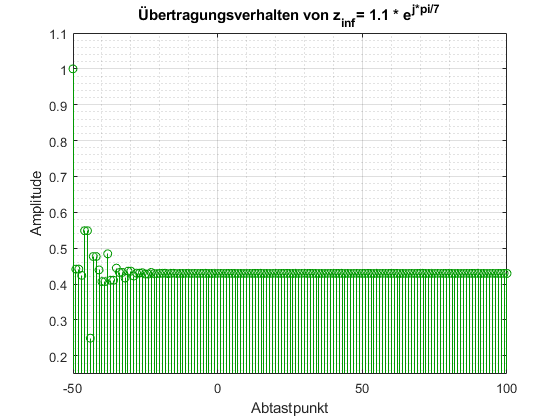


x= z1.^k;                        %komplexe Exponentialfolge
y = IIR(x,2,coef1,coef2);       %Filterung der Folge mit bekanntem IIR-Filter
q = y ./ x;                   %Quotient aus Ausgangssignal zu Eingangssignal

figure(9)
stem (k,abs(q),'Color',[0 0.6 0])
stem_properties('Übertragungsverhalten von z_{inf}= 1.1 * e^{j*pi/7}', 'Abtastpunkt', 'Amplitude', abs(q))
xlim([-50 100])

#### z_inf = 1.2*e^(j*(6pi/5)

z2= 1.2 * exp(1j*6*pi/5);

losung2 = ((1.2 * exp(1j*6*pi/5))^2)/(((1.2 * exp(1j*6*pi/5))^2)+(0.9*(1.2 * exp(1j*6*pi/5)))+0.81);
losung3 = ((z2)^2)/(((z2)^2)+(0.9*(z2))+0.81);

Y2=polyval(coef1,z2);       %Auswertung des Zählerpolynoms
X2=polyval(coef2,z2);       %Auswertung des Nennerpolynoms

H_z2 = Y2/X2

H_z2 = 1.7162 + 0.2849i

abs(H_z1)

ans = 0.4298

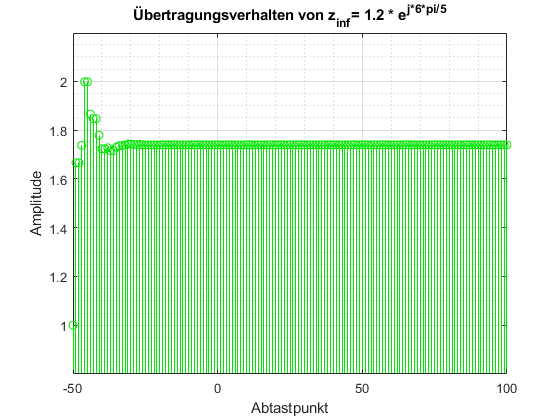


x= z2.^k;                        %komplexe Exponentialfolge
y = IIR(x,2,coef1,coef2);       %Filterung der Folge mit bekanntem IIR-Filter
q = y ./ x;                   %Quotient aus Ausgangssignal zu Eingangssignal

figure(10)
stem (k,abs(q),'Color',[0 0.9 0])
stem_properties('Übertragungsverhalten von z_{inf}= 1.2 * e^{j*6*pi/5}', 'Abtastpunkt', 'Amplitude', abs(q))
xlim([-50 100])

#### Plot

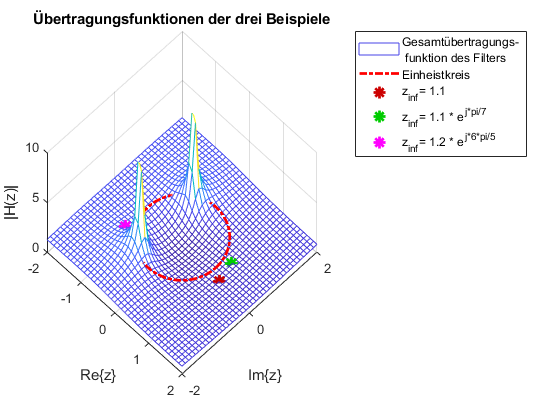

figure (11);
Kreisumfang = linspace (0, 2*pi);           %Erstellung des Einheitskreises      
x = cos(Kreisumfang);
y = sin(Kreisumfang);
mesh (x_Real, y_Imag, abs(x2))                          %Plotten vom 3D-Raum
line(x, y , 1.5*ones(size(Kreisumfang)),'linewidth',2,'Color','red','LineStyle','-.')
line(real(z), imag(z) , abs(H_z),'Marker','*','Color',[0.8 0 0],"MarkerSize",10,'linewidth',2,'LineStyle','none')
line(real(z1), imag(z1) , abs(H_z1),'Marker','*','Color',[0 0.8 0],"MarkerSize",10,'linewidth',2,'LineStyle','none')
line(real(z2), imag(z2) , abs(H_z2),'Marker','*','Color','m',"MarkerSize",10,'linewidth',2,'LineStyle','none')
view([45 60])                                           %schräge Ansicht
xlim ([-2 2])
ylim ([-2 2])
zlim ([0 10]); 
caxis ([0,10]);                          %caxis = Limit für die Colormap
xlabel ('Re\{z\}')                       %(Achsenbeschriftung wie in Vorlesung)
ylabel ('Im\{z\}')
zlabel ('|H(z)|')
title  ('Übertragungsfunktionen der drei Beispiele')
legend('Gesamtübertragungs- \newline funktion des Filters', 'Einheistkreis', 'z_{inf}= 1.1', 'z_{inf}= 1.1 * e^{j*pi/7}', 'z_{inf}= 1.2 * e^{j*6*pi/5}')